## **Setup**


clear
clc


data1 = load('EMGDataMyFingerDry.mat');
data2 = load('EMGDataMyFistDry.mat');
data3 = load('EMGDataMyOKDry.mat');

% Convert the row to a numeric array
data_EMGDataMyFinger = table2array(data1.EMGDataMyFingerdry);
data_EMGDataMyFist = table2array(data2.EMGDataMyFistdry);
data_EMGDataMyOK = table2array(data3.EMGDataMyOKdry);

%{
data_EMGDataMyFinger = load('EMGDataMyFingerwrist.mat');
data_EMGDataMyFist = load('EMGDataMyFistwrist.mat');
data_EMGDataMyOK = load('EMGDataMyOKwrist.mat');
%}

n = 120;

X = [data_EMGDataMyFinger; data_EMGDataMyFist; data_EMGDataMyOK];
    
Y(1:n,1) = 1;
Y((n+1):(n*2),1) = 2;
Y(((n*2)+1):(n*3),1) = 3;

wv = 'db10'; %wavelet family

## 5 by 2 CV

Cross Validation allows us to compare different machine learning methods and get a sense of how well they will work in practice.

We do two things:

- Estimate the paramenters for the machine learning methods (Training)

- Evalutae how well the machine learning methods work (Testing)

seeds = [13 51 137 24659 347]; % Random seeds for reproducibility

for i = 1:length(seeds)
    
    rng(seeds(i)); % Set the random seed for reproducibility
    cv = cvpartition(Y,'kfold',2); % Create a 2-fold cross-validation object
    
    for j = 1:cv.NumTestSets
        % Training data for the j-th fold
        Xtr = X(cv.training(j),:); % Extract training features
        Ytr = Y(cv.training(j)); % Extract training labels
        
        % Test data for the j-th fold
        Xts = X(cv.test(j),:); % Extract test features
        Yts = Y(cv.test(j)); % Extract test labels

        % At this point, you would typically train a model using (Xtr, Ytr)
        % and then evaluate it using (Xts, Yts).

## Train

        [mx,my] = size(Xtr); % Get the size of the training data (mx = number of samples, my = number of features)
        
        for k=1:mx
            ch_tr = Xtr(k,:); % Get the k-th row of the training data, representing one sample

            if(~isnan(ch_tr)) % Check if the data contains any NaN values
                
                dwt = modwt(ch_tr,wv); % Perform a MODWT (Maximal Overlap Discrete Wavelet Transform) on the sample
                
                % Calculate Statistical Features
                kurt = kurtosis(ch_tr); % Kurtosis
                skew = skewness(ch_tr); % Skewness
                vari = var(ch_tr); % Variance
                %rmse = sqrt(mean(ch_tr.^2)); % Root Mean Square Error (RMSE)
                mav = mean(abs(ch_tr)); % Mean Absolute Value (MAV)
                %zcd = length(zerocross(ch_tr)); % Number of zero crossings
                %iemg = trapz(abs(ch_tr))/length(ch_tr);
                
                % Calculate Features from Wavelet Coefficients
                energy_by_scales = sum(dwt.^2,2); % Calculate the energy at each scale from the wavelet coefficients
                stdv = std(dwt')'; % Calculate the standard deviation of the wavelet coefficients for each scale
                
                % Combine these features into a single feature vector for the k-th sample
                Xtrain(:,k) = [energy_by_scales; kurt; skew; vari; mav; stdv];
            end
        end

## Test

        [nx,ny] = size(Xts);
        
        for k=1:nx
            ch_ts = Xts(k,:);
            if(~isnan(ch_ts))
                dwt = modwt(ch_ts,wv);
                kurt = kurtosis(ch_ts);
                skew = skewness(ch_ts);
                vari = var(ch_ts);
                %rmse = sqrt(mean(ch_ts.^2));
                mav = mean(abs(ch_ts));
                %zcd = length(zerocross(ch_ts));
                %iemg = trapz(abs(ch_tr))/length(ch_tr);
                energy_by_scales = sum(dwt.^2,2);
                stdv = std(dwt')';
                Xtest(:,k) = [energy_by_scales; kurt; skew; vari; mav; stdv];
            end
        end

## Autoencoder Parameters

Network Struct

      
        hiddenSize1 = 1105;
        autoenc1 = trainAutoencoder(Xtrain,hiddenSize1, ...
            'MaxEpochs',100, ...
            'L2WeightRegularization',0.004, ...
            'SparsityRegularization',8, ...
            'SparsityProportion',0.15, ...
            'DecoderTransferFunction', 'logsig', ...
            'ScaleData', false);
        
        features1 = encode(autoenc1,Xtrain);
        
        Ytrain = full(ind2vec(Ytr'));
        
        % Softmax layer train
        softnet = trainSoftmaxLayer(features1,Ytrain,'MaxEpochs',1000);
        
        % Stacking
        deepnet = stack(autoenc1,softnet);
        deepnet = train(deepnet,Xtrain,Ytrain);
        
        label_deep = vec2ind(deepnet(Xtest));
        label_prob = deepnet(Xtest);
        AccRate_deep(i,j) = sum(Yts' == label_deep)/length(Yts); % Compute accuracy
        C_deep{i,j} = confusionmat(Yts,label_deep); % Confusion matrix
  

## **DNN**

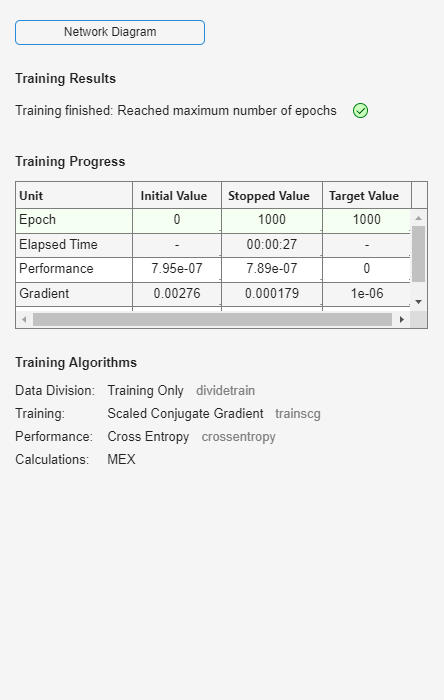


        % Convert Y labels to categorical
        numClasses = numel(unique(Ytr));
        Ytrain = categorical(Ytr);
        Xtrain = Xtrain';
    
        % Define DNN architecture
        layers = [
            featureInputLayer(size(Xtrain, 2), 'Normalization', 'zscore')
        
            fullyConnectedLayer(1024)
            batchNormalizationLayer
            leakyReluLayer(0.1)
            dropoutLayer(0.4)  % Increase dropout
        
            fullyConnectedLayer(512)
            batchNormalizationLayer
            leakyReluLayer(0.1)
            dropoutLayer(0.3)
        
            fullyConnectedLayer(256)
            batchNormalizationLayer
            leakyReluLayer(0.1)
            dropoutLayer(0.3)
        
            fullyConnectedLayer(numClasses)
            softmaxLayer
            classificationLayer
        ];

        % Training options
        options = trainingOptions('adam', ...
            'MaxEpochs', 300, ...
            'MiniBatchSize', 64, ...
            'InitialLearnRate', 0.001, ...
            'LearnRateSchedule', 'piecewise', ...
            'LearnRateDropFactor', 0.5, ...
            'LearnRateDropPeriod', 50, ...
            'Shuffle', 'every-epoch', ...
            'ValidationFrequency', 10, ...
            'Verbose', false, ...
            'ExecutionEnvironment', 'auto');

    
        % Train the DNN
        net = trainNetwork(Xtrain, Ytrain, layers, options);

        % Close training progress window
        pause(1); % Short delay to ensure window appears before closing
        h = findall(groot, 'Type', 'Figure', 'Name', 'Training Progress');
        close(h);

        label_dnn = classify(net, Xtest');
        Yts_cat = categorical(Yts);
        AccRate_dnn(i,j) = sum(Yts_cat == label_dnn)/length(Yts_cat);
        C_dnn{i,j} = confusionmat(Yts_cat,label_dnn);

        fprintf('DNN Accuracy: %.2f%%\n', AccRate_dnn(i,j) * 100);
        
        Xtrain = Xtrain';
      

DNN Accuracy: 71.11%
DNN Accuracy: 77.22%
DNN Accuracy: 76.11%
DNN Accuracy: 74.44%
DNN Accuracy: 76.67%
DNN Accuracy: 78.89%
DNN Accuracy: 82.22%
DNN Accuracy: 76.11%
DNN Accuracy: 77.78%
DNN Accuracy: 74.44%


## KNN

        KNN4 = fitcknn(Xtrain',Ytr,'NumNeighbors',4);
        label_knn4 = predict(KNN4,Xtest');
        AccRate_knn4(i,j) = sum(Yts == label_knn4)/length(Yts);
        C_knn4{i,j} = confusionmat(Yts,label_knn4);

        KNN5 = fitcknn(Xtrain',Ytr,'NumNeighbors',5);
        label_knn5 = predict(KNN5,Xtest');
        AccRate_knn5(i,j) = sum(Yts == label_knn5)/length(Yts);
        C_knn5{i,j} = confusionmat(Yts,label_knn5);

        KNN6 = fitcknn(Xtrain',Ytr,'NumNeighbors',6);
        label_knn6 = predict(KNN6,Xtest');
        AccRate_knn6(i,j) = sum(Yts == label_knn6)/length(Yts);
        C_knn6{i,j} = confusionmat(Yts,label_knn6);

## SVM

        tSVM = templateSVM('Standardize',1,'KernelFunction','linear');
        SVM = fitcecoc(Xtrain',Ytr,'Learners',tSVM);
        label_svm = predict(SVM,Xtest');
        AccRate_svm(i,j) = sum(Yts == label_svm)/length(Yts);
        C_svm{i,j} = confusionmat(Yts,label_svm);

        tSVM2 = templateSVM('Standardize',1,'KernelFunction','polynomial');
        SVM2 = fitcecoc(Xtrain',Ytr,'Learners',tSVM2);
        label_svm2 = predict(SVM2,Xtest');
        AccRate_svm2(i,j) = sum(Yts == label_svm2)/length(Yts);
        C_svm2{i,j} = confusionmat(Yts,label_svm2);

        tSVM3 = templateSVM('Standardize',1,'KernelFunction','rbf');
        SVM3 = fitcecoc(Xtrain',Ytr,'Learners',tSVM3);
        label_svm3 = predict(SVM3,Xtest');
        AccRate_svm3(i,j) = sum(Yts == label_svm3)/length(Yts);
        C_svm3{i,j} = confusionmat(Yts,label_svm3);

        tSVM4 = templateSVM('Standardize',1,'KernelFunction','gaussian');
        SVM4 = fitcecoc(Xtrain',Ytr,'Learners',tSVM4);
        label_svm4 = predict(SVM4,Xtest');
        AccRate_svm4(i,j) = sum(Yts == label_svm4)/length(Yts);
        C_svm4{i,j} = confusionmat(Yts,label_svm4);



## LDA

        LDA = fitcdiscr(Xtrain', Ytr, 'DiscrimType', 'pseudoLinear');
        label_lda = predict(LDA,Xtest');
        AccRate_lda(i,j) = sum(Yts == label_lda)/length(Yts);
        C_lda{i,j} = confusionmat(Yts,label_lda);

    end
end

## Accuracy


mean(AccRate_deep(:)) % Mean

ans = 0.4239

%{
SEM_deep = std(AccRate_deep(:))/sqrt(length(AccRate_deep(:))); % Standard Error
ts_deep = tinv([0.025  0.975],length(AccRate_deep(:))-1);      % T-Score
CI_deep = mean(AccRate_deep(:)) + ts_deep*SEM_deep; % Confidence Interval
(ts_deep*SEM_deep)*100 % Margin of Error
%}


mean(AccRate_knn4(:))

ans = 0.8211

%{
SEM_knn4 = std(AccRate_knn4(:))/sqrt(length(AccRate_knn4(:)));  % Standard Error
ts_knn4 = tinv([0.025  0.975],length(AccRate_knn4(:))-1);      % T-Score
CI_knn4 = mean(AccRate_knn4(:)) + ts_knn4*SEM_knn4;
ts_knn4*SEM_knn4*100
%}

mean(AccRate_knn5(:))

ans = 0.8144

%{
SEM_knn5 = std(AccRate_knn5(:))/sqrt(length(AccRate_knn5(:)));  % Standard Error
ts_knn5 = tinv([0.025  0.975],length(AccRate_knn5(:))-1);      % T-Score
CI_knn5 = mean(AccRate_knn5(:)) + ts_knn5*SEM_knn5;
ts_knn5*SEM_knn5*100
%}

mean(AccRate_knn6(:))

ans = 0.8111

%{
SEM_knn6 = std(AccRate_knn6(:))/sqrt(length(AccRate_knn6(:)));  % Standard Error
ts_knn6 = tinv([0.025  0.975],length(AccRate_knn6(:))-1);      % T-Score
CI_knn6 = mean(AccRate_knn6(:)) + ts_knn6*SEM_knn6;
ts_knn6*SEM_knn6*100
%}

mean(AccRate_svm(:))

ans = 0.8239

%{
SEM_svm = std(AccRate_svm(:))/sqrt(length(AccRate_svm(:)));  % Standard Error
ts_svm = tinv([0.025  0.975],length(AccRate_svm(:))-1);      % T-Score
CI_svm = mean(AccRate_svm(:)) + ts_svm*SEM_svm;
ts_svm*SEM_svm*100
%}

mean(AccRate_svm2(:))

ans = 0.7228

%{
SEM_svm2 = std(AccRate_svm2(:))/sqrt(length(AccRate_svm2(:)));  % Standard Error
ts_svm2 = tinv([0.025  0.975],length(AccRate_svm2(:))-1);      % T-Score
CI_svm2 = mean(AccRate_svm2(:)) + ts_svm2*SEM_svm2;
ts_svm2*SEM_svm2*100
%}

mean(AccRate_svm3(:))

ans = 0.7772

%{
SEM_svm3 = std(AccRate_svm3(:))/sqrt(length(AccRate_svm3(:)));  % Standard Error
ts_svm3 = tinv([0.025  0.975],length(AccRate_svm3(:))-1);      % T-Score
CI_svm3 = mean(AccRate_svm3(:)) + ts_svm3*SEM_svm3;
ts_svm3*SEM_svm3*100
%}

mean(AccRate_svm4(:))

ans = 0.7772

%{
SEM_svm4 = std(AccRate_svm4(:))/sqrt(length(AccRate_svm4(:)));  % Standard Error
ts_svm4 = tinv([0.025  0.975],length(AccRate_svm4(:))-1);      % T-Score
CI_svm4 = mean(AccRate_svm4(:)) + ts_svm4*SEM_svm4;
ts_svm4*SEM_svm4*100
%}

mean(AccRate_lda(:))

ans = 0.7844

%{
SEM_lda = std(AccRate_lda(:))/sqrt(length(AccRate_lda(:)));  % Standard Error
ts_lda = tinv([0.025  0.975],length(AccRate_lda(:))-1);      % T-Score
CI_lda = mean(AccRate_lda(:)) + ts_lda*SEM_lda;
ts_lda*SEM_lda*100
%}


mean(AccRate_dnn(:))

ans = 0.7650

%{
SEM_dnn = std(AccRate_dnn(:))/sqrt(length(AccRate_dnn(:)));  % Standard Error
ts_dnn = tinv([0.025  0.975],length(AccRate_dnn(:))-1);      % T-Score
CI_dnn = mean(AccRate_dnn(:)) + ts_dnn*SEM_dnn;
ts_dnn*SEM_dnn*100
%}


## Get Statistical Results

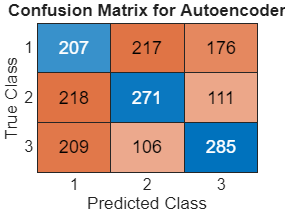

%(1) Cylindrical: for holding cylindrical tools
%(2) Hook: for supporting a heavy load
%(3) Tip: for holding small tools
%(4) Palmar: for grasping with palm facing the object
%(5) Spherical: for holding spherical tools
%(6) Lateral: for holding thin, flat objects

[row,col] = size(C_knn4{1,1});

confMatrix_deep = zeros(row,col);
confMatrix_knn4 = zeros(row,col);
confMatrix_knn5 = zeros(row,col);
confMatrix_knn6 = zeros(row,col);
confMatrix_svm = zeros(row,col);
confMatrix_svm2 = zeros(row,col);
confMatrix_svm3 = zeros(row,col);
confMatrix_svm4 = zeros(row,col);
confMatrix_lda = zeros(row,col);
confMatrix_dnn = zeros(row,col);



for i = 1:5
    for j = 1:2
        confMatrix_deep = confMatrix_deep + C_deep{i,j};
        confMatrix_knn4 = confMatrix_knn4 + C_knn4{i,j};
        confMatrix_knn5 = confMatrix_knn5 + C_knn5{i,j};
        confMatrix_knn6 = confMatrix_knn6 + C_knn6{i,j};
        confMatrix_svm = confMatrix_svm + C_svm{i,j};
        confMatrix_svm2 = confMatrix_svm2 + C_svm2{i,j};
        confMatrix_svm3 = confMatrix_svm3 + C_svm3{i,j};
        confMatrix_svm4 = confMatrix_svm4 + C_svm4{i,j};
        confMatrix_lda = confMatrix_lda + C_lda{i,j};
        confMatrix_dnn = confMatrix_dnn + C_dnn{i,j};
        
    end
end

[result_deep,reference_deep]= getStatistical(confMatrix_deep);
[result_knn4,reference_knn4]= getStatistical(confMatrix_knn4);
[result_knn5,reference_knn5]= getStatistical(confMatrix_knn5);
[result_knn6,reference_knn6]= getStatistical(confMatrix_knn6);
[result_svm,reference_svm]= getStatistical(confMatrix_svm);
[result_svm2,reference_svm2]= getStatistical(confMatrix_svm2);
[result_svm3,reference_svm3]= getStatistical(confMatrix_svm3);
[result_svm4,reference_svm4]= getStatistical(confMatrix_svm4);
[result_lda,reference_lda]= getStatistical(confMatrix_lda);
[result_dnn,reference_dnn]= getStatistical(confMatrix_dnn);



% Display the confusion matrix for each models


confusionchart(confMatrix_deep);
title('Confusion Matrix for Autoencoder');

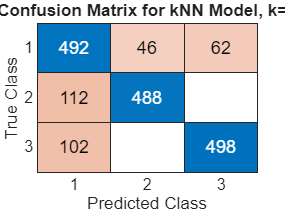



confusionchart(confMatrix_knn4);
title('Confusion Matrix for kNN Model, k=4');

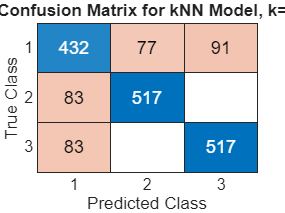


confusionchart(confMatrix_knn5);
title('Confusion Matrix for kNN Model, k=5');

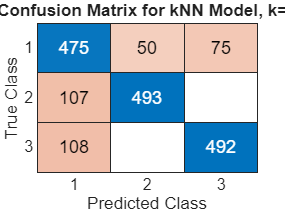


confusionchart(confMatrix_knn6);
title('Confusion Matrix for kNN Model, k=6');

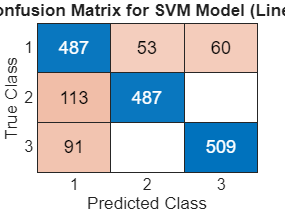


confusionchart(confMatrix_svm);
title('Confusion Matrix for SVM Model (Linear)');

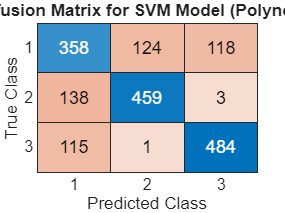


confusionchart(confMatrix_svm2);
title('Confusion Matrix for SVM Model (Polynomial)');

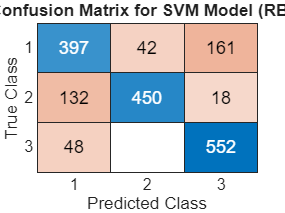


confusionchart(confMatrix_svm3);
title('Confusion Matrix for SVM Model (RBF)');

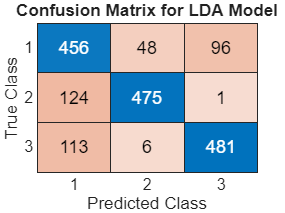


confusionchart(confMatrix_lda);
title('Confusion Matrix for LDA Model');

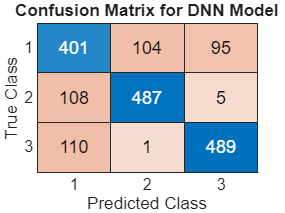



confusionchart(confMatrix_dnn);
title('Confusion Matrix for DNN Model');